# PRÁCTICA 7: CARACTERÍSTICAS LOCALES DE LA IMAGEN (1º PARTE)

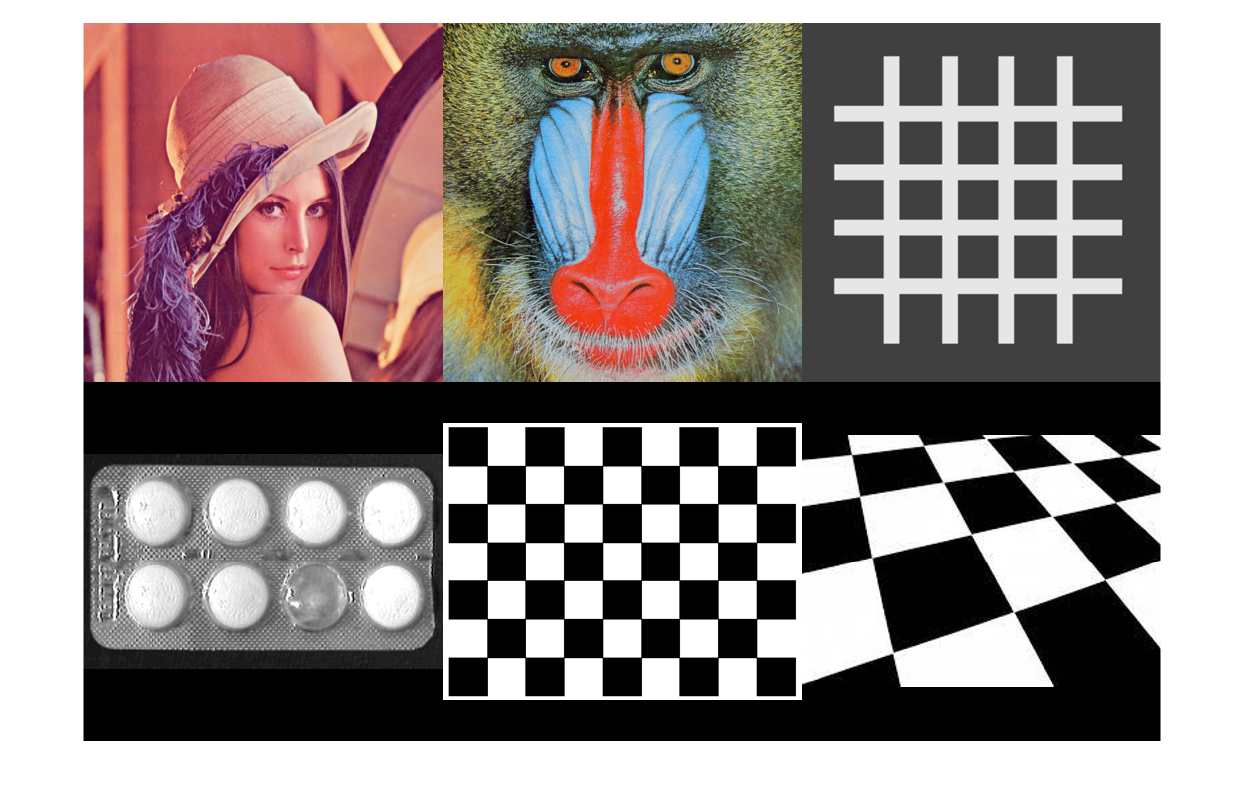

% Cargamos las imágenes que utilizaremos en la práctica.

lena = imread("lena_color_512.tif");
mandril = imread("mandril_color.tif");
malla = imread("patron_malla.jpg");
textura = imread("astablet.tif");
chessboard = imread("chessboardpattern.jpg");
chessboard_inclinado = imread("esquinas_perspectiva.jpg");

malla = rgb2gray(malla);
chessboard_inclinado = rgb2gray(chessboard_inclinado);

montage({lena,mandril,malla,textura,chessboard,chessboard_inclinado})

## Caracteristicas basadas en el histograma

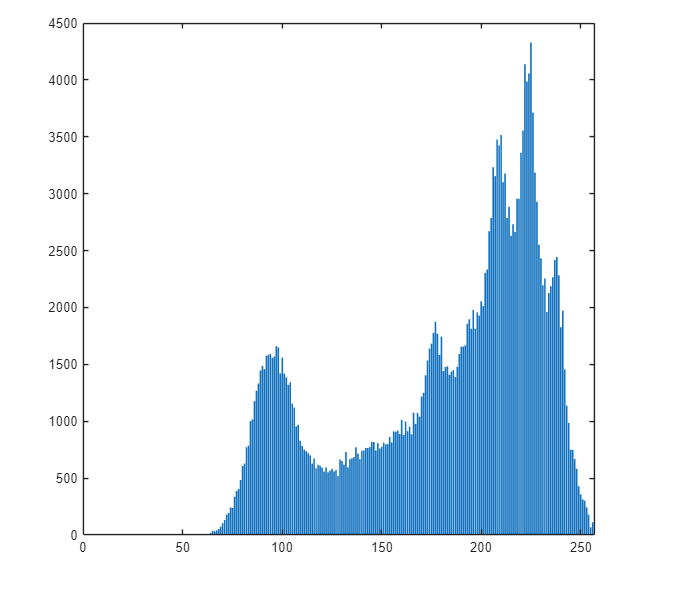

% Histograma del color

lena_red = lena(:,:,1);
lena_green = lena(:,:,2);
lena_blue = lena(:,:,3);

lena_red_hist = imhist(lena_red);
lena_green_hist = imhist(lena_green);
lena_blue_hist = imhist(lena_blue);

bar(lena_red_hist)

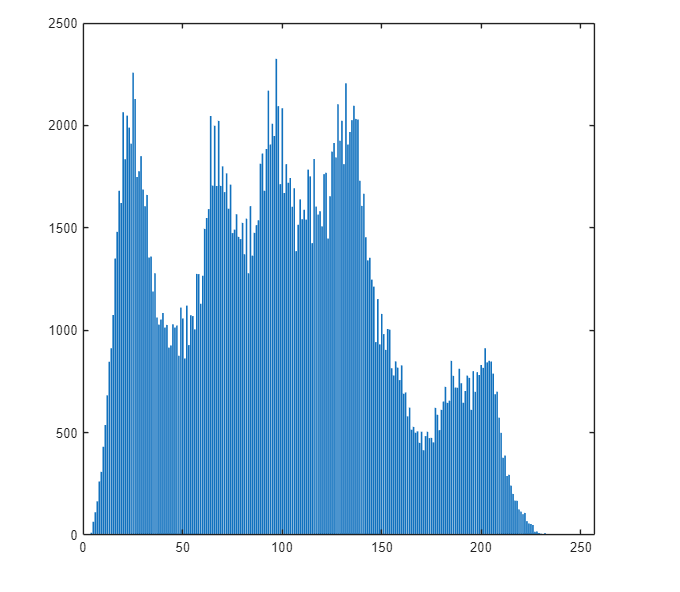

bar(lena_green_hist)

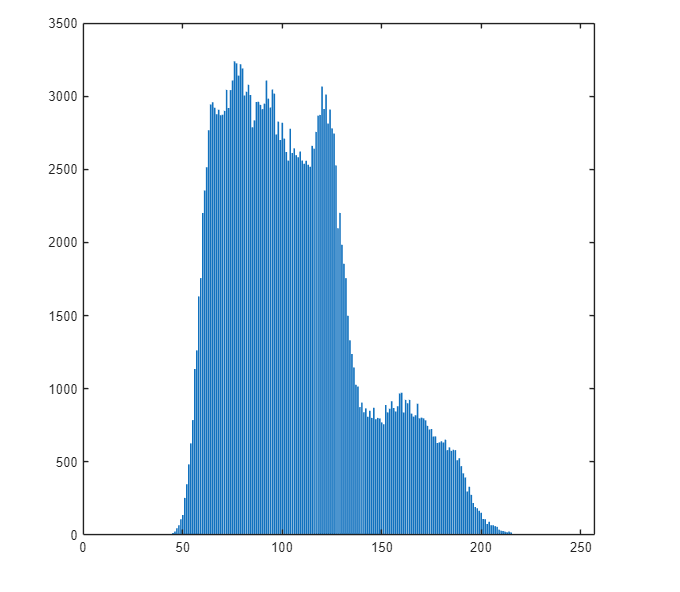

bar(lena_blue_hist)

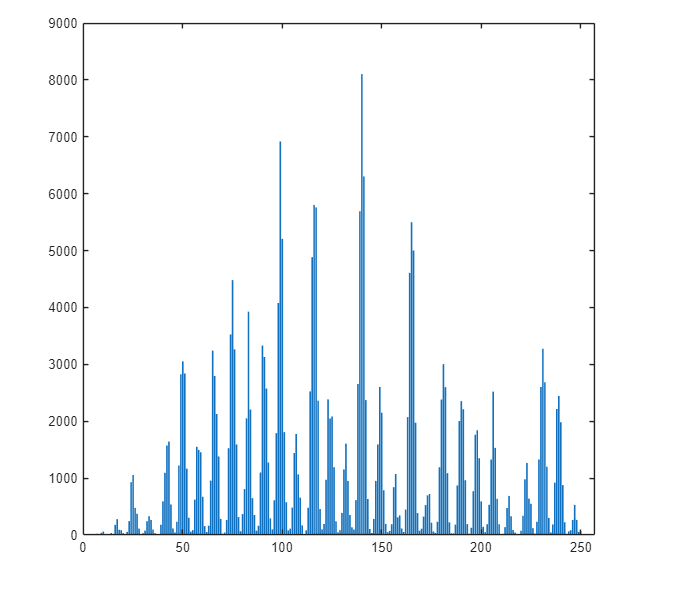


% Primer ejemplo: Lena

% Separamos la imagen en los tres canales de color

% Obtenemos los histogramas de cada canal

% Otro ejemplo: Mandril

mandril_red = mandril(:,:,1);
mandril_green = mandril(:,:,2);
mandril_blue = mandril(:,:,3);

mandril_red_hist = imhist(mandril_red);
mandril_green_hist = imhist(mandril_green);
mandril_blue_hist = imhist(mandril_blue);

bar(mandril_red_hist)

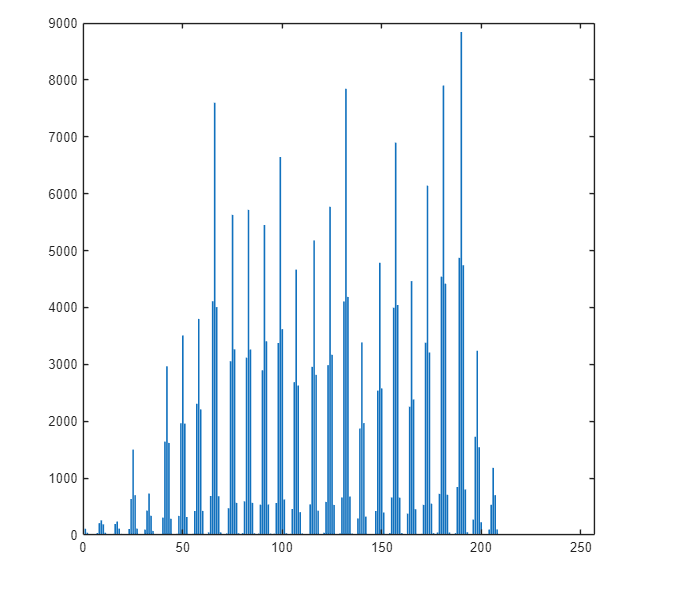

bar(mandril_green_hist)

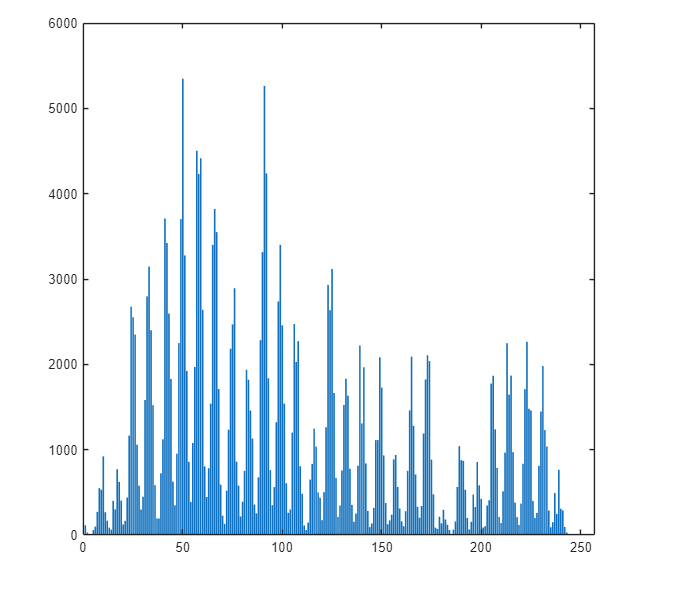

bar(mandril_blue_hist)


% Medidas de similitud para comparar histogramas

% Para simplificar, vamos a comparar solo un histograma por imagen

% Normalizamos el histograma

lena_red_hist_normalizado = lena_red_hist/numel(lena_red);
mandril_red_hist_normalizado = mandril_red_hist/numel(mandril_red);

% Distancia Euclidea

distancia_euclidea = sqrt(sum((lena_red_hist_normalizado-mandril_red_hist_normalizado).^2))

distancia_euclidea = 0.1042


%%% Para ser pequeña debería ser 0.0...

% Distancia Xi-cuadrado

distancia_xi_cuadrado = sum(((lena_red_hist_normalizado-mandril_red_hist_normalizado).^2)./(lena_red_hist_normalizado+mandril_red_hist_normalizado+eps))

distancia_xi_cuadrado = 0.8395


% Distancia de la divergencia de Jeffrey

distancia_jeffrey = sum(lena_red_hist_normalizado.*log(lena_red_hist_normalizado./(mandril_red_hist_normalizado+eps)+eps))

distancia_jeffrey = 1.5083


% Histograma de los gradientes orientados

[vector,hog_visual] = extractHOGFeatures(lena)

vector = 1×142884 single row vector
    0.2171    0.0573    0.1047    0.1579    0.1192    0.1047    0.2171    0.1232    0.2171    0.1680    0.1845    0.1826    0.1801    0.1624    0.1715    0.2142    0.2171    0.1590    0.2171    0.0779    0.0508    0.1936    0.1289    0.1462    0.1530    0.1175    0.2171    0.1382    0.2171    0.0995    0.1715    0.1324    0.1766    0.2060    0.2166    0.1334    0.1902    0.2081    0.1683    0.1674    0.1755    0.1768    0.1527    0.2081    0.1701    0.1772    0.1743    0.0896    0.1384    0.1930


hog_visual = Visualization

   Type plot(hog_visual) to visualize.

   Read-only properties:
                CellSize: [8 8]
               BlockSize: [2 2]
            BlockOverlap: [1 1]
                 NumBins: 9
    UseSignedOrientation: 0
              BinCenters: [18×1 double]


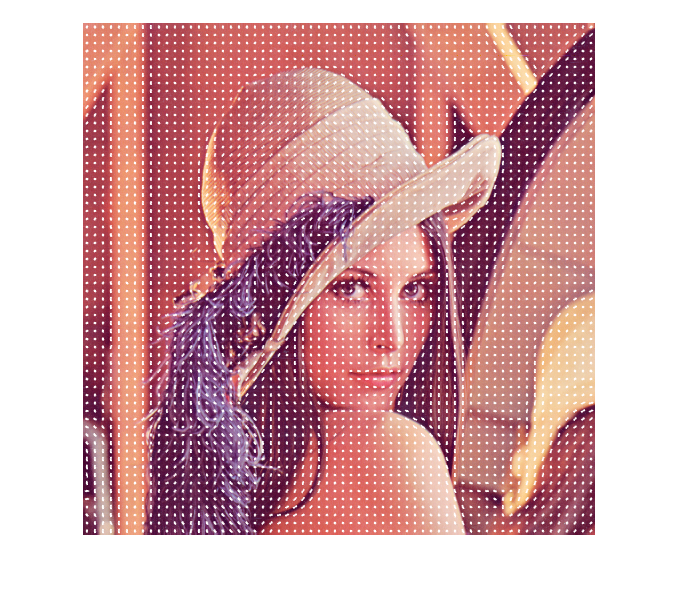


imshow(lena)
hold on
plot(hog_visual)
hold off


% Primer ejemplo: Lena

% Comando

% Otro ejemplo: Mandril

imshow(mandril)

hold on
[vector_mandril, hog_visual_mandril] = extractHOGFeatures(mandril)

vector_mandril = 1×142884 single row vector
    0.2372    0.2372    0.2372    0.1164    0.0650    0.0468    0.0380    0.0766    0.1765    0.2332    0.2372    0.2372    0.2035    0.1001    0.0641    0.0370    0.0628    0.1483    0.1955    0.2372    0.2167    0.1666    0.0711    0.0805    0.1394    0.0865    0.1332    0.2372    0.2372    0.2372    0.2130    0.0925    0.1256    0.1564    0.0644    0.1742    0.2253    0.2424    0.2424    0.1983    0.1193    0.0667    0.0364    0.0756    0.1324    0.1720    0.2286    0.2424    0.1404    0.1098


hog_visual_mandril = Visualization

   Type plot(hog_visual_mandril) to visualize.

   Read-only properties:
                CellSize: [8 8]
               BlockSize: [2 2]
            BlockOverlap: [1 1]
                 NumBins: 9
    UseSignedOrientation: 0
              BinCenters: [18×1 double]


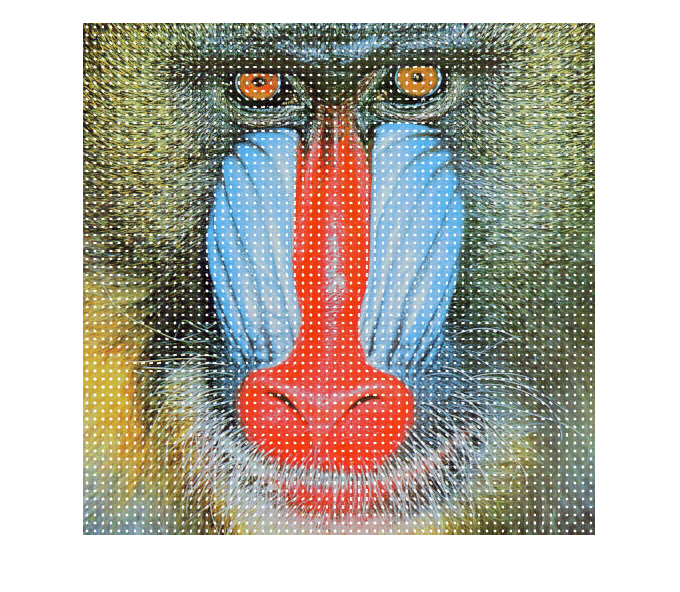

plot(hog_visual_mandril)
hold off

## Caracteristicas basadas en la transformada de Hough

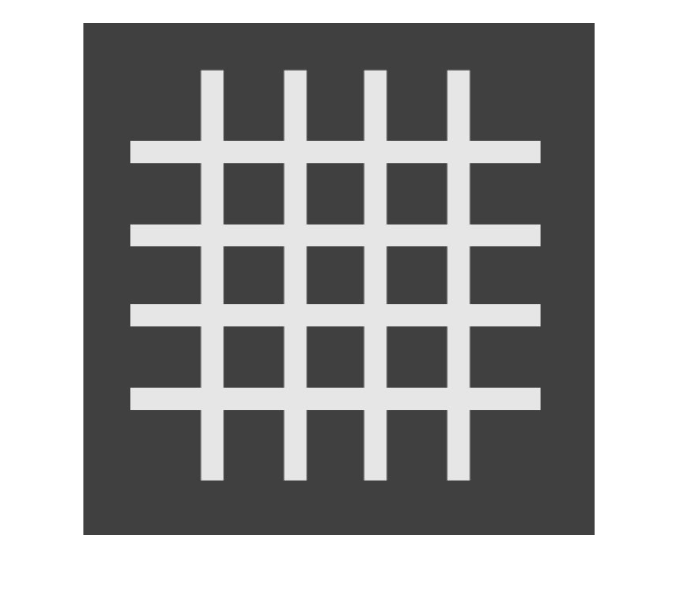

% Rectas
imshow(malla)

% Primero obtenemos los bordes de la imagen

malla_bordes = edge(malla);

[H,T,R] = hough(malla_bordes)

H =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

T =    -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51   -50   -49   -48   -47   -46   -45   -44   -43   -42   -41


R =   -922  -921  -920  -919  -918  -917  -916  -915  -914  -913  -912  -911  -910  -909  -908  -907  -906  -905  -904  -903  -902  -901  -900  -899  -898  -897  -896  -895  -894  -893  -892  -891  -890  -889  -888  -887  -886  -885  -884  -883  -882  -881  -880  -879  -878  -877  -876  -875  -874  -873



% Comando Hough para detectar lineas

% Calculando los picos (puntos con más valor) en el espacio
% de Hough

P = houghpeaks(H,16,"Threshold",ceil(0.4*max(H(:))));

lineas = houghlines(malla_bordes,T,R,P)

lineas = 1×80 struct array with fields:
    point1
    point2
    theta
    rho


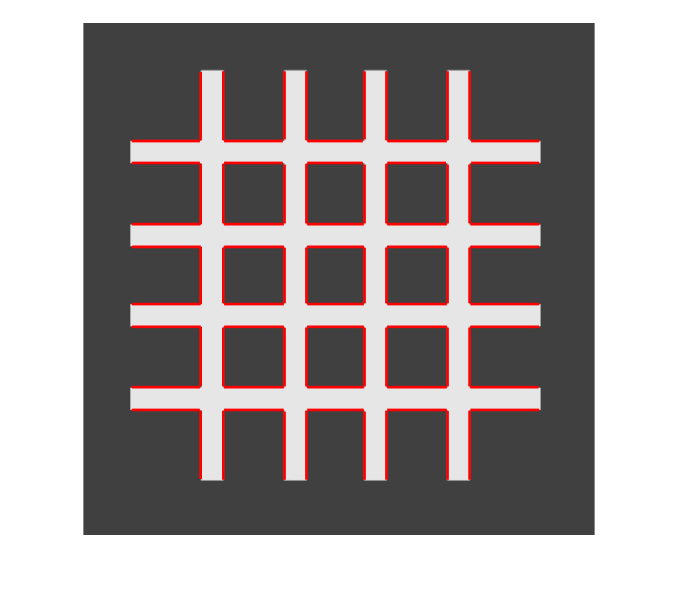


imshow(malla)

hold on

for i = 1:1:length(lineas)

    xy = [lineas(i).point1;lineas(i).point2];

    plot(xy(:,1),xy(:,2),Color='r',LineWidth=2)
end

hold off

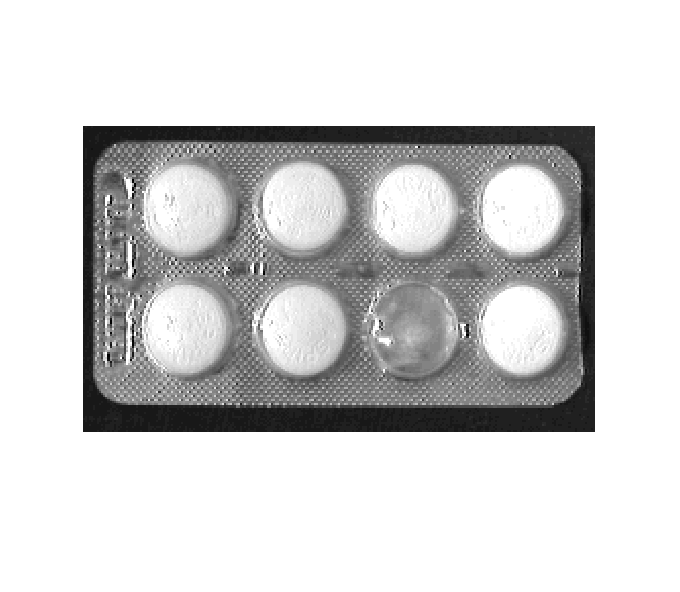


% Circulos

imshow(textura)

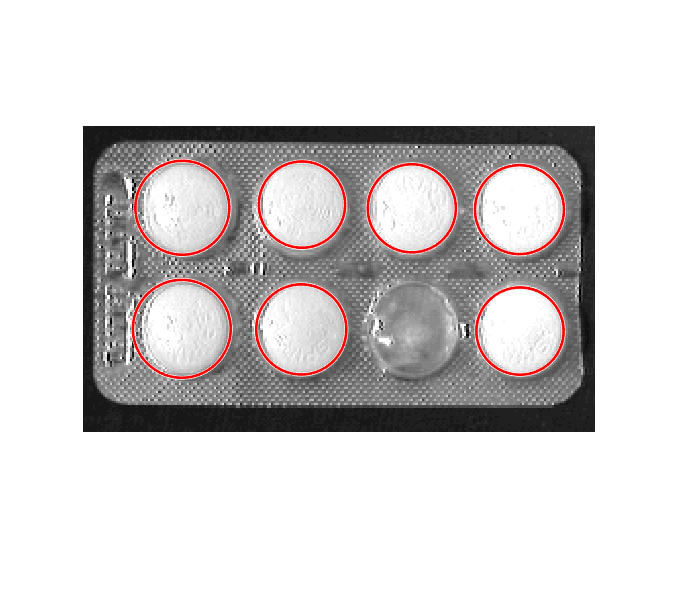


[centros,radios]=imfindcircles(textura,[6 50]);

imshow(textura)
viscircles(centros,radios,Color='r',LineWidth=2);

## Vertices

% Metodo de Harris
chessboard_esquinas = detectHarrisFeatures(chessboard)

chessboard_esquinas =   128×1 cornerPoints array with properties:

    Location: [128×2 single]
      Metric: [128×1 single]
       Count: 128


chessboard_esquinas_coordenadas = chessboard_esquinas.Location;
chessboard_esquinas_coordenadas

chessboard_esquinas_coordenadas = 128×2 single matrix
   12.5613    8.5565
   12.5523   71.4477
   12.5534  135.5607
   12.5638  198.4407
   12.5534  263.5607
   12.5638  326.4407
   12.5534  391.5607
   12.5520  453.4565
   75.2950   72.7070
   75.2977  134.3056
   75.2671  199.7413
   75.2977  262.3056
   75.2671  327.7413
   75.2977  390.3056
   75.4514    8.5527


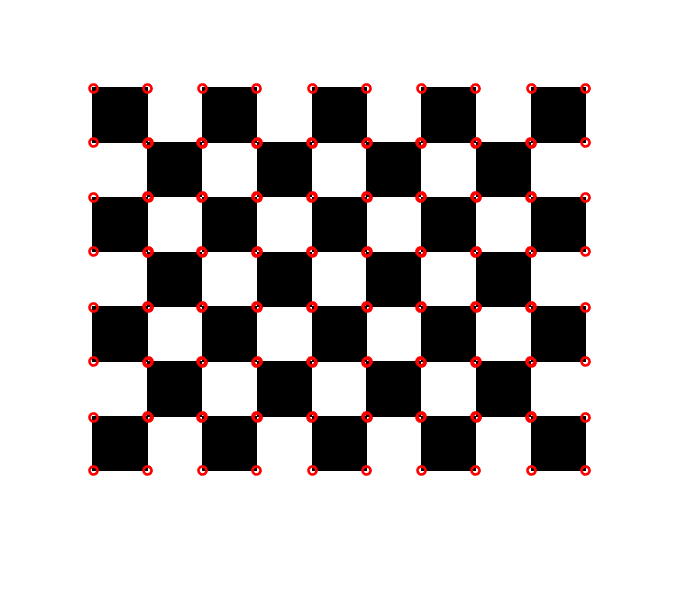

imshow(chessboard)
hold on
plot(chessboard_esquinas_coordenadas(:,1),chessboard_esquinas_coordenadas(:,2),'o', Color= 'r',LineWidth=2)
hold off

% Otro ejemplo
chessboard_esquinas2 = detectHarrisFeatures(chessboard_inclinado)

chessboard_esquinas2 =   51×1 cornerPoints array with properties:

    Location: [51×2 single]
      Metric: [51×1 single]
       Count: 51


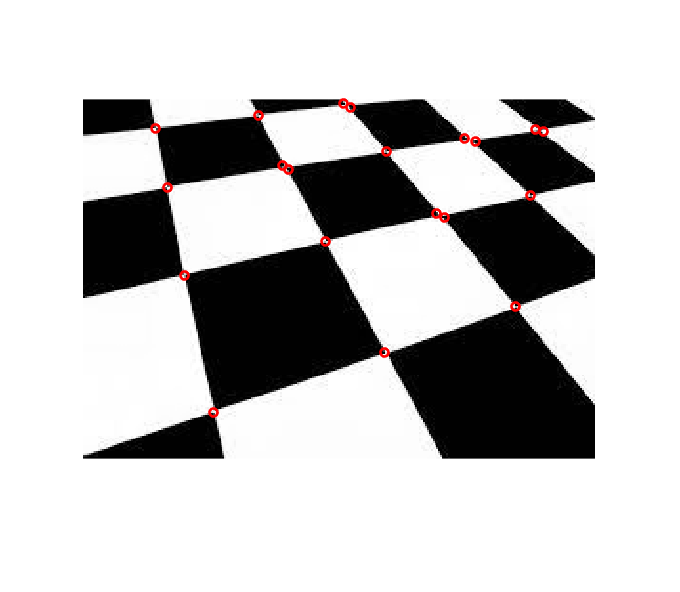

chessboard_esquinas2 = chessboard_esquinas2.selectStrongest(20);

chessboard_esquinas_coordenadas2 = chessboard_esquinas2.Location;
imshow(chessboard_inclinado)
hold on
plot(chessboard_esquinas_coordenadas2(:,1),chessboard_esquinas_coordenadas2(:,2),'o', Color= 'r',LineWidth=2)
hold off

## Ejercicios

% Para las imagenes "flores", "modelo_1" y "modelo_2":
% 
% 1. Usa el histograma del color para determinar a cuál de los dos 
% modelos es igual la imagen "flores".

flores=imread("flores.tif");
modelo1 = imread("modelo_1.tif");
modelo2 = imread("modelo_2.tif");

flores_red = flores(:,:,1);
flores_green = flores(:,:,2);
flores_blue = flores(:,:,3);

modelo1_red = modelo1(:,:,1);
modelo1_green = modelo1(:,:,2);
modelo1_blue = modelo1(:,:,3);

modelo2_red = modelo2(:,:,1);
modelo2_green = modelo2(:,:,2);
modelo2_blue = modelo2(:,:,3);

flores_red_hist_norm = imhist(flores_red)/numel(flores_red);
flores_green_hist_norm = imhist(flores_green)/numel(flores_green);
flores_blue_hist_norm = imhist(flores_blue)/numel(flores_blue);

modelo1_red_hist_norm = imhist(modelo1_red)/numel(modelo1_red);
modelo1_green_hist_norm = imhist(modelo1_green)/numel(modelo1_green);
modelo1_blue_hist_norm = imhist(modelo1_blue)/numel(modelo1_blue);

modelo2_red_hist_norm = imhist(modelo2_red)/numel(modelo2_red);
modelo2_green_hist_norm = imhist(modelo2_green)/numel(modelo2_green);
modelo2_blue_hist_norm = imhist(modelo2_blue)/numel(modelo2_blue);

distancia_euclidea_model1_red = sqrt(sum((flores_red_hist_norm-modelo1_red_hist_norm).^2));
distancia_euclidea_model1_green = sqrt(sum((flores_green_hist_norm-modelo1_green_hist_norm).^2));
distancia_euclidea_model1_blue = sqrt(sum((flores_blue_hist_norm-modelo1_blue_hist_norm).^2));
media_modelo1 = (distancia_euclidea_model1_red+distancia_euclidea_model1_green+distancia_euclidea_model1_blue)/3

media_modelo1 = 0.0287


distancia_euclidea_model2_red = sqrt(sum((flores_red_hist_norm-modelo2_red_hist_norm).^2));
distancia_euclidea_model2_green = sqrt(sum((flores_green_hist_norm-modelo2_green_hist_norm).^2));
distancia_euclidea_model2_blue = sqrt(sum((flores_blue_hist_norm-modelo2_blue_hist_norm).^2));
media_modelo2 = (distancia_euclidea_model2_red+distancia_euclidea_model2_green+distancia_euclidea_model2_blue)/3

media_modelo2 = 0.0452

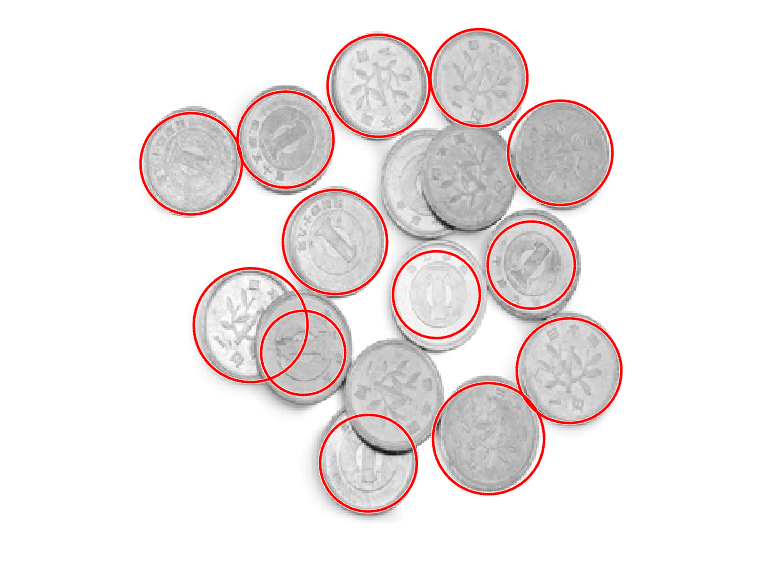

%% Vemos como el modelo 1 tiene mayor parecido que el 2 aunque por poco.

% Para las imágenes "coins", "coins_modelo1", coins_modelo2" y
% "coins_modelo3":
%
% 1. Usa el la transformada de Hough para determinar a cuál de los
% tres modelos es igual a la imagen "coins".
%
% NOTAS:
% 1.1 A veces no es posible encontrar todos los círculos, pero si se
% encuentran suficientes, la comparación entre imágenes es posible.
% 1.2 Considera reescalar espacialmente las imágenes para mejorar la
% detección y comparación.
% 1.3 La detección mejora enormenten si en vez de usar la imagen original,
% usamos una imagen solo con los bordes.
monedas = imread("coins.jpg");
monedas_m1 = imread("coins_modelo1.png");
monedas_m2 = imread("coins_modelo2.jpg");
monedas_m3 = imread("coins_modelo3.jpg");

% Convertimos a escala de grises
monedas = rgb2gray(monedas);
monedas_m2 = rgb2gray(monedas_m2);
monedas_m3 = rgb2gray(monedas_m3);

% Reescalamos las imagenes
monedas = imresize(monedas,[300,300]);
monedas_m1 = imresize(monedas_m1,[300,300]);
monedas_m2 = imresize(monedas_m2,[300,300]);
monedas_m3 = imresize(monedas_m3,[300,300]);


% Aplicamos detección de bordes con Canny 
monedas_bordes = edge(monedas,'Canny');
monedas_m1_bordes = edge(monedas_m1,'Canny');
monedas_m2_bordes = edge(monedas_m2,'Canny');
monedas_m3_bordes = edge(monedas_m3,'Canny');

% Detectamos círculos
[centros, radios] = imfindcircles(monedas_bordes,[20 100]);
[centros1, radios1] = imfindcircles(monedas_m1_bordes,[20 100]);
[centros2, radios2] = imfindcircles(monedas_m2_bordes,[20 100]);
[centros3, radios3] = imfindcircles(monedas_m3_bordes,[20 100]);

% Mostramos resultados
imshow(monedas)
viscircles(centros,radios,Color='r');

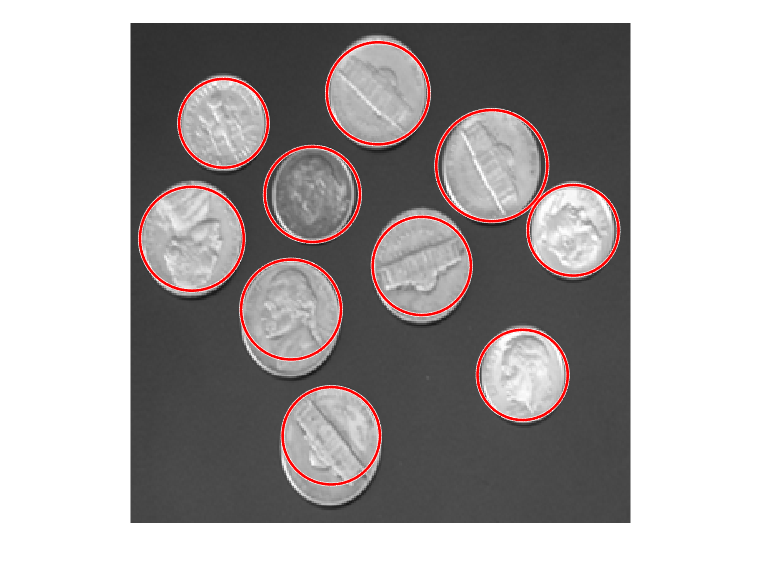


imshow(monedas_m1)
viscircles(centros1,radios1,Color='r');

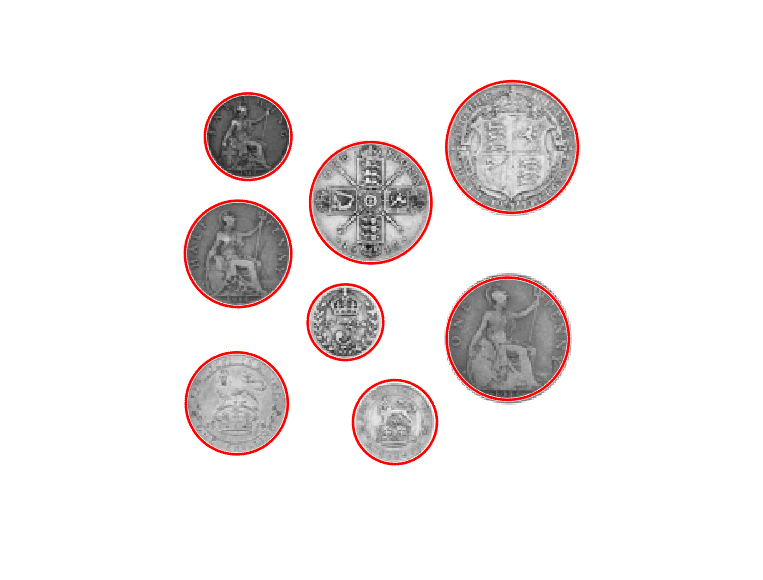


imshow(monedas_m2)
viscircles(centros2,radios2,Color='r');


imshow(monedas_m3)
viscircles(centros3,radios3,Color='r');


% Comparamos por número de círculos detectados
n_coins = size(centros,1);
n_m1 = size(centros1,1);
n_m2 = size(centros2,1);
n_m3 = size(centros3,1);


% Calculamos similitud por diferencia en el número de círculos
diff1 = abs(n_coins - n_m1)

diff1 = 3

diff2 = abs(n_coins - n_m2)

diff2 = 5

diff3 = abs(n_coins - n_m3)

diff3 = 0

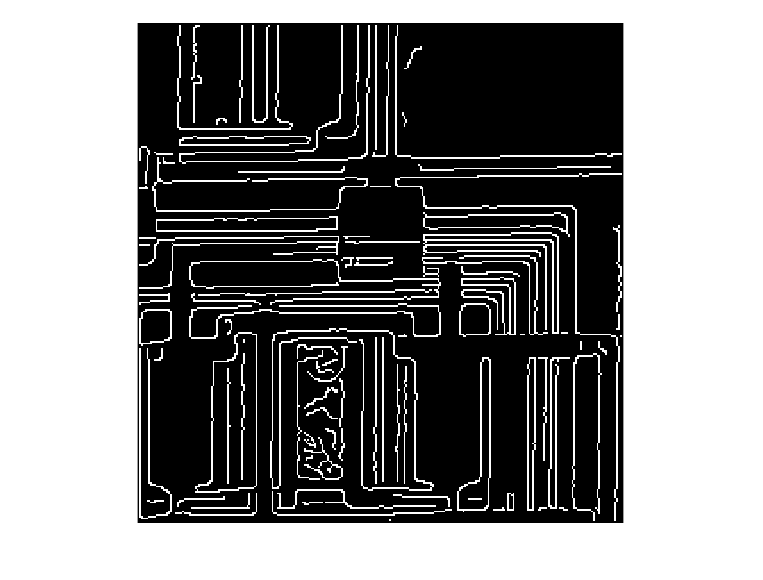


%% Vemos como el modelo 3 es el que no presenta diferencia sobre el numero
% de circulos detectados con referencia a la imagen original por lo que nos
% indica que es la imagen más parecida según lo indicado en el ejhercicio y
% efectivamente así es.

% Para la imagen "circuit":
%
% 1. Detectar y pintar la mayoría de rectas usando la transformada 
% de Hough y calcular cuál de ellas es la que tiene mayor longitud.
% Píntala de otro color para distinguirla.

circuit = imread("circuit.png");

% Detectamos los bordes
circuit_bordes = edge(circuit,"canny");
imshow(circuit_bordes)

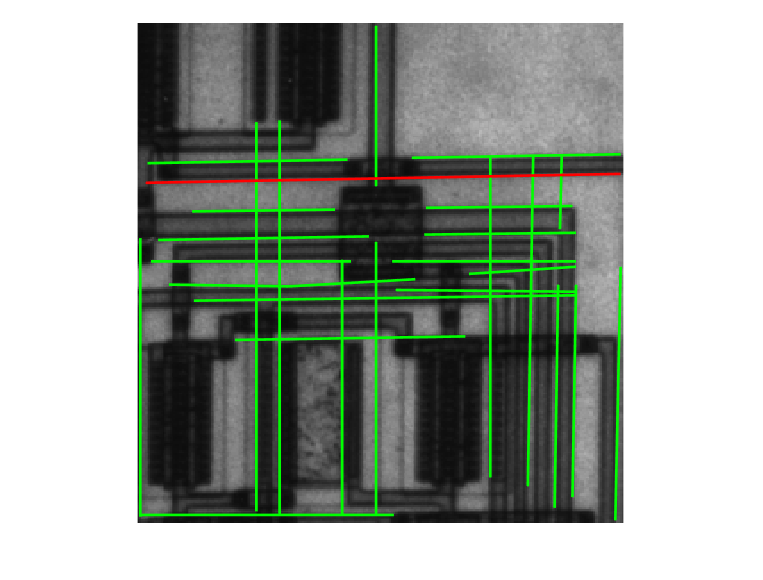

% Aplicamos transformada de Hough
[H,T,R] = hough(circuit_bordes);

% Picos de Hough
P = houghpeaks(H,20,"Threshold",ceil(0.4*max(H(:))));

% Líneas
lineas = houghlines(circuit_bordes,T,R,P);

imshow(circuit)
hold on

max_len = 0;
xy_long = [];

for k = 1:length(lineas)
    xy = [lineas(k).point1; lineas(k).point2];
    plot(xy(:,1),xy(:,2),LineWidth=2,Color='g');
    
    % Longitud de la línea
    len = norm(lineas(k).point1 - lineas(k).point2);
    if len > max_len
        max_len = len;
        xy_long = xy;
    end
end

% Dibujamos la línea más larga en rojo
plot(xy_long(:,1),xy_long(:,2),LineWidth=2,Color='r');
hold off



% Para la imagen "placa_calibracio":
%
% 1. Desarrolla un sistema de calibración sabiendo que la placa de la
% imagen es una placa solida de PVC, diseñada con un laser de alta pre-
% cisión, y que los circulos han sido impresos en la placa de forma que
% la distancia vertical u horizontal entre los centros de cualquier par 
% de circulos es siempre de 10 mm.

%% Ejercicio: Calibración con placa de puntos

placa = imread("placa_calibracio.jpg");
placa_gray = rgb2gray(placa);

% Mejorar contraste y detección
placa_gray = imadjust(placa_gray);
placa_bordes = edge(placa_gray,'Canny');

% Detección de círculos (según tamaño aproximado)
[centros, radios] = imfindcircles(placa_gray,[10 40],'Sensitivity',0.9);

figure, imshow(placa), title('Círculos detectados en la placa');
viscircles(centros,radios,'Color','r','LineWidth',2);

% Calcular distancia media entre centros adyacentes
distancias = pdist2(centros,centros);
distancias(distancias==0) = NaN;
distancia_media_px = nanmean(distancias(:));

% Calibración: sabemos que la distancia real entre centros = 10 mm
mm_por_pixel = 10 / distancia_media_px;

fprintf('Distancia media entre centros: %.2f píxeles\n', distancia_media_px);
fprintf('Escala obtenida: %.4f mm/píxel\n', mm_por_pixel);